# Object Detection with Machine Learning

This script replicates what was covered in the video "Object Detection with Machine Learning". Additionally, at the end are some useful metrics for evaluating detection results. You will later use these metrics for the final detection project.

### Loading the Ground Truth Data

The ground truth for the railroad signs dataset is stored in a ".mat" file in the course files. To access the ground truth data, you'll need to load it and then update the image file locations to match your system. To do this, run the following section of code.

load RRsignsGroundTruth.mat

Overwrite the image file locations stored in the ground truth variable to match your system.

testPath = overwriteGTruthLocations(gTruthTest,gTruthTrain);


All the file paths are resolved in this groundTruth object.

All the file paths are resolved in this groundTruth object.


### Training the ACF Object Detector

Convert the ground truth variable into a table that the function `trainACFObjectDetector` can use.

objectTrainingData = objectDetectorTrainingData(gTruthTrain)

objectTrainingData = 90×2 table
                                                                    imageFilename                                                                         RRXingSign     
    ______________________________________________________________________________________________________________________________________________    ___________________

    {'C:\Users\Asad PC\Documents\MATLAB\Computer Vision for Engineering and Science\Data\MathWorks Images\Railroad Signs\Train\RRXingSign_01.JPG'}    {[357 379 316 323]}
    {'C:\Users\Asad PC\Documents\MATLAB\Computer Vision for Engineering and Science\Data\MathWorks Images\Railroad Signs\Train\RRXingSign_02.JPG'}    {[627 317 309 316]}
    {'C:\Users\Asad PC\Documents\MATLAB\Computer Vision for Engineering and Science\Data\MathWorks Images\Railroad Signs\Train\RRXingSign_03.JPG'}    {[629 207 343 333]}
    {'C:\Users\Asad PC\Documents\MATLAB\Computer 

Train the detector. This step may take a few minutes to run.

acfDetector = trainACFObjectDetector(objectTrainingData)

ACF Object Detector Training
The training will take 4 stages. The model size is 206x205.
Sample positive examples(~100% Completed)
Compute approximation coefficients...Completed.
Compute aggregated channel features...Completed.
--------------------------------------------
Stage 1:
Sample negative examples(~100% Completed)
Compute aggregated channel features...Completed.
Train classifier with 90 positive examples and 450 negative examples...Completed.
The trained classifier has 20 weak learners.
--------------------------------------------
Stage 2:
Sample negative examples(~100% Completed)
Found 279 new negative examples for training.
Compute aggregated channel features...Completed.
Train classifier with 90 positive examples and 450 negative examples...Completed.
The trained classifier has 19 weak learners.
--------------------------------------------
Stage 3:
Sample negative examples(~100% Completed)
Found 450 new negative examples for training.
Compute aggregated channel features...Co

acfDetector =   acfObjectDetector with properties:

             ModelName: 'RRXingSign'
    ObjectTrainingSize: [206 205]
       NumWeakLearners: 25


### Detect Using the Trained Detector

Run this section to apply the detector on the test images. First, load the test images as an image datastore.

imdsTest = imageDatastore(testPath)

imdsTest =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\MathWorks Images\Railroad Signs\Test\RRXingSign_001.JPG';
                              ' ...\Data\MathWorks Images\Railroad Signs\Test\RRXingSign_002.JPG';
                              ' ...\Data\MathWorks Images\Railroad Signs\Test\RRXingSign_003.JPG'
                               ... and 7 more
                              }
                     Folders: {
                              ' ...\Data\MathWorks Images\Railroad Signs\Test'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


Run the detector.

bboxes = detect(acfDetector,imdsTest)

bboxes = 10×2 table
           Boxes              Scores   
    ___________________    ____________

    {[420 148 375 377]}    {[ 90.4952]}
    {[208 170 375 377]}    {[105.7780]}
    {0×4 double       }    {0×1 double}
    {[636 285 315 317]}    {[105.7780]}
    {[811 544 244 245]}    {[ 99.5406]}
    {[273 186 315 317]}    {[ 83.8488]}
    {[372 118 315 317]}    {[ 88.4189]}
    {[427 346 410 412]}    {[ 88.9790]}
    {[673 211 244 245]}    {[ 57.2164]}
    {0×4 double       }    {0×1 double}


Insert the ground truth and detection results over each image. The ground truth bounding boxes are added as green rectangles and the detected bounding boxes as a yellow rectangle with a detection score. If a yellow rectangle is missing, that means the detector missed a sign.

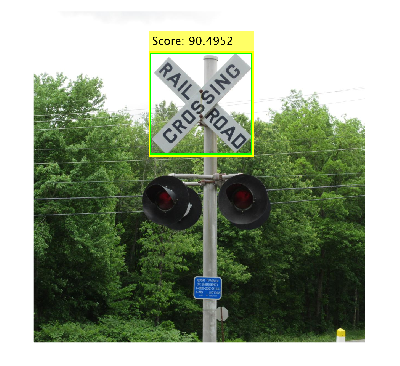

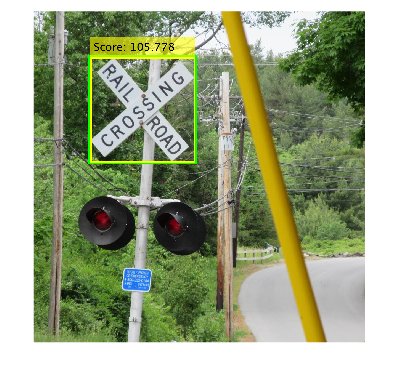

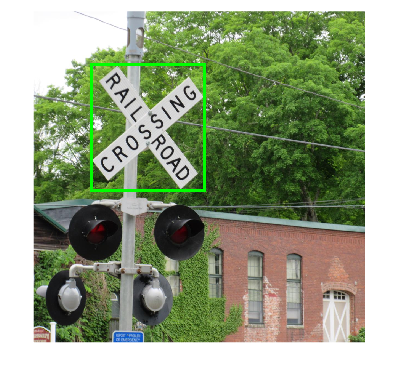

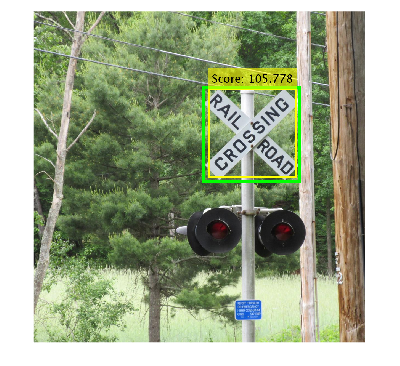

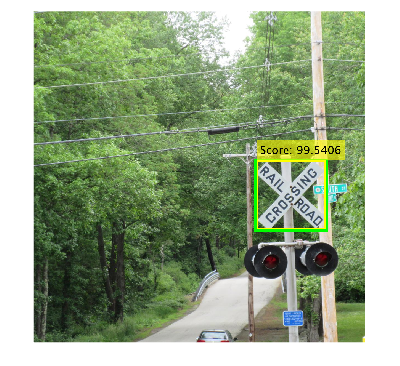

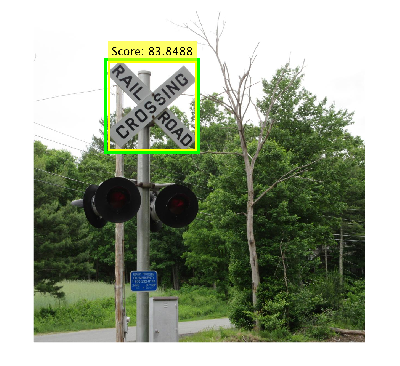

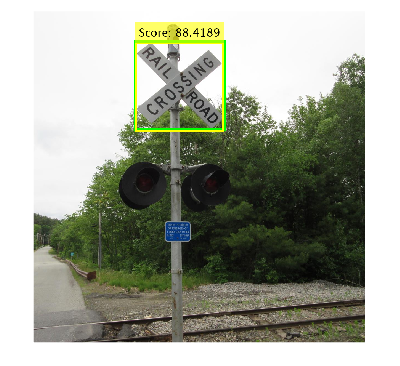

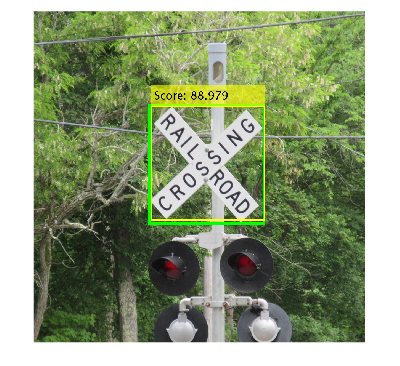

for idx = 1:height(imdsTest.Files)
    % Load the image
    img = readimage(imdsTest,idx);
    
    % Insert the ground truth bounding box
    img = insertShape(img,"Rectangle",gTruthTest.LabelData.RailRoadXingSign{idx},...
        "Color","green","LineWidth",10);
    
    % Insert the detected bounding box
    img = insertObjectAnnotation(img,"Rectangle",bboxes.Boxes{idx},...
        "Score: " + bboxes.Scores{idx},"FontSize",40,"LineWidth",6);
    
    % Display the image
    figure
    imshow(img)
end

### Evaluate the Results

Intersection over Union

A standard method for quantifying the accuracy of a single bounding box is to calculate its overlap ratio with the ground truth, also known as the Intersection over Union (IoU).

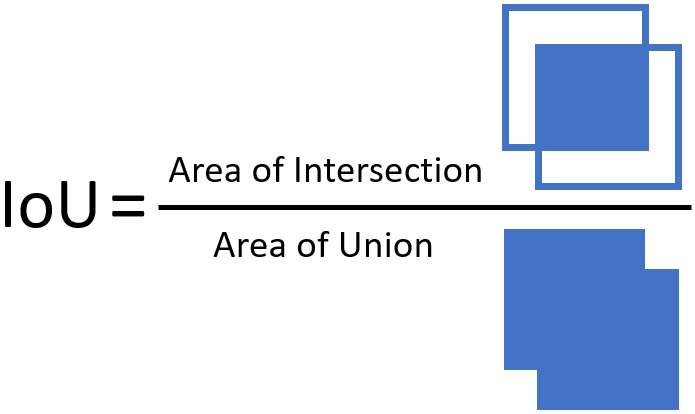

For example, here is the IoU value for one of the images.

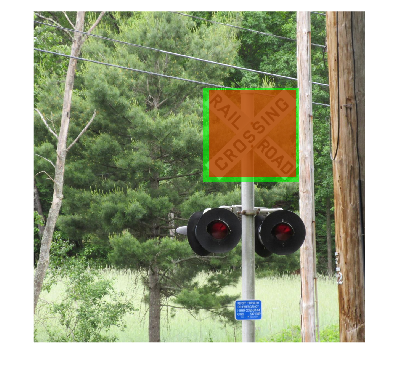

idx = 4;
img = readimage(imdsTest,idx);
gTruthBbox = gTruthTest.LabelData.RailRoadXingSign{idx};
detectionBbox = bboxes.Boxes{idx};
img = insertShape(img,"filled-rectangle",gTruthBbox,"Color","green");
img = insertShape(img,"filled-rectangle",detectionBbox,"Color","red");
imshow(img)


overlapRatio = bboxOverlapRatio(gTruthBbox,detectionBbox)

overlapRatio = 0.8415

A value of 0 means no overlap, and a value of 1 means perfect overlap.

Miss Rate and Precision

To measure the average performance of a detector over a collection of images, use the detection [miss rate](https://www.mathworks.com/help/vision/ref/evaluatedetectionmissrate.html) and [precision](https://www.mathworks.com/help/vision/ref/evaluatedetectionprecision.html). Both metrics count a detection as "correct" if its IoU is above a threshold value (0.5 by default).

**Miss Rate:** Quantifies how many ground truth objects received no correct detections. This metric is log-averaged over all detections and scales from:

- 0 - if **all** the ground truth objects were detected.

- 1 - if **none** of the ground truth objects were detected. 

evaluateDetectionMissRate(bboxes,gTruthTest.LabelData)

ans = 0.2000

**Precision:** Quantifies how many detections were correct out of all detections. Note that if a ground truth object receives multiple detections, then only one of them is marked "correct". This metric is log-averaged over all detections and scales from:

- 0 - if **none** of the detections were correct.

- 1 - if **all** the detections were correct. 

evaluateDetectionPrecision(bboxes,gTruthTest.LabelData)

ans = 0.8000

### Further Practice

In this example, the default trained detector missed the signs in 2 of the 10 test images, resulting in a miss rate of 0.2. See if you can adjust the options available for training the [`trainACFObjectDetector`](https://www.mathworks.com/help/vision/ref/trainacfobjectdetector.html) or [`detect`](https://www.mathworks.com/help/vision/ref/acfobjectdetector.detect.html) functions to achieve a lower miss rate without also reducing the precision.

% Put your code here



#### Helper Function

This function overwrites the image file locations stored in the ground truth variable to match your system.

function testPath = overwriteGTruthLocations(gTruthTest,gTruthTrain)
% Find the location of the image files
testPath = fileparts(which("RRXingSign_001.JPG"));
if isempty(testPath)
    error("The course files are not on the MATLAB search path." + ...
        "Follow the instructions when downloading the course files to add them to your path.")
end

% Overwrite locations for test images
currentPath = string(fileparts(gTruthTest.DataSource.Source{1}));
changeFilePaths(gTruthTest,[currentPath, testPath]);

% Overwrite locations for training images
trainPath = erase(testPath,'Test') + "Train";
currentPath = string(fileparts(gTruthTrain.DataSource.Source{1}));
changeFilePaths(gTruthTrain,[currentPath, trainPath]);
end

*Copyright 2022 The MathWorks, Inc.*